# Earth Season Demonstration

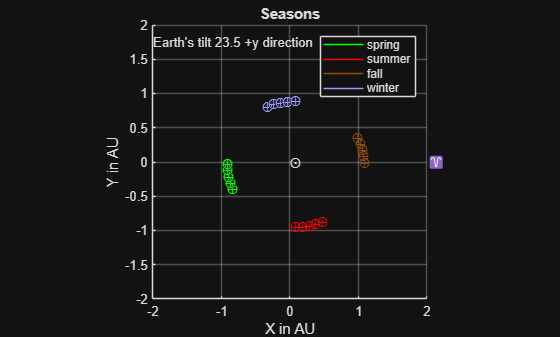

clearvars
clf
h2f = figure(1);
h2a = axes(h2f);
h2a.XLim = [-2 2];
h2a.YLim = [-2 2];
text(h2a,0,0,0,SUN.SYMBOL);
text(h2a,+2,0,0,EARTH.ARIES);
axis(h2a,'square')
hold on;

% Spring 2025 is March     20
% Summer 2025 is June      20
% Fall   2025 is September 22
% Winter 2025 is December  21

springJD = EARTH.calendarToJulianDay(2025,  3, 20, 0, 0, 0);
summerJD = EARTH.calendarToJulianDay(2025,  6, 20, 0, 0, 0);
fallJD   = EARTH.calendarToJulianDay(2025,  9, 22, 0, 0, 0);
winteJD  = EARTH.calendarToJulianDay(2025, 12, 21, 0, 0, 0);

for ii = 1:6:30
   [x,y,z] = EARTH.positionVector(springJD+ii);
   if ii == 1
      plot3(x,y,z,"Color",'#00FF00')
   end
   text(h2a, x, y, z, EARTH.SYMBOL, "Color","#00FF00");

   [x,y,z] = EARTH.positionVector(summerJD+ii);
   if ii == 1
      plot3(x,y,z,"Color",'#FF0000')
   end
   text(h2a, x, y, z, EARTH.SYMBOL, "Color","#FF0000");

   [x,y,z] = EARTH.positionVector(fallJD+ii);
   if ii == 1
      plot3(x,y,z,"Color","#964B00")
   end
   text(h2a, x, y, z, EARTH.SYMBOL, "Color","#964B00");

   [x,y,z] = EARTH.positionVector(winteJD+ii);
   if ii == 1
      plot3(x,y,z,"Color","#9999ff")
   end
   text(h2a, x, y, z, EARTH.SYMBOL, "Color","#9999ff");
end

title("Seasons");
xlabel("X in AU");
ylabel("Y in AU");
text(-2,1.75,"Earth's tilt 23.5 +y direction")
grid
legend({"spring","summer","fall","winter"})